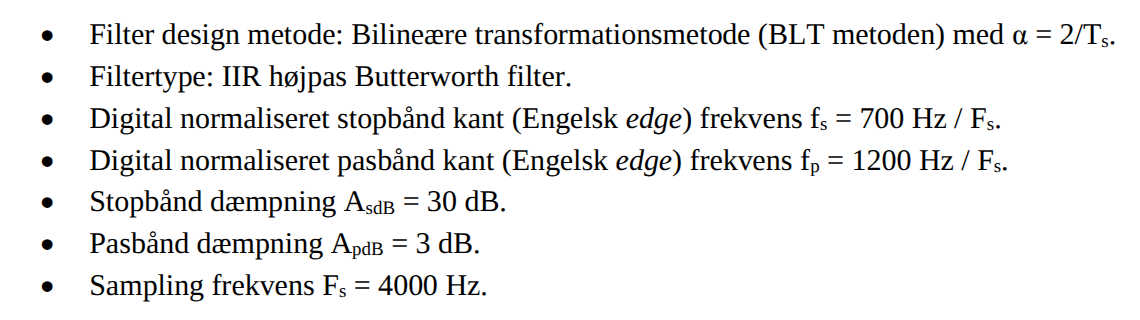

f_s = 700; f_p = 1200; A_sdB = 30; A_pdB = 3; F_s = 4e3;

omega_p = (2*pi*f_p)/F_s; omega_s = (2*pi*f_s)/F_s;

Omega_p = 2*F_s*tan(omega_p/2)

Omega_p = 1.1011e+04

Omega_s = 2*F_s*tan(omega_s/2)

Omega_s = 4.9024e+03


nu = Omega_p/Omega_s;

n_value(A_sdB, A_pdB, nu)

e = 1.000000
n = 5.000000

b_p = 1; a_p = [1 3.2361 5.2361 5.2361 3.2361 1];

H_proto = tf(b_p, a_p)


H_proto =
 
                            1
  -----------------------------------------------------
  s^5 + 3.236 s^4 + 5.236 s^3 + 5.236 s^2 + 3.236 s + 1
 
Continuous-time transfer function.


For højpas filter er transformationen $s\longrightarrow \frac{\Omega_p }{s}$

[bt, at] = lp2hp(b_p, a_p, Omega_p);

H_hp = tf(bt, at)


H_hp =
 
                            s^5 + 1.133e-07 s^3
  -----------------------------------------------------------------------
  s^5 + 3.563e04 s^4 + 6.348e08 s^3 + 6.99e12 s^2 + 4.757e16 s + 1.619e20
 
Continuous-time transfer function.


For at transformere til z domene skal $s=\frac{2}{T_s }\cdot \frac{z-1}{z+1}$

[bd, ad] = bilinear(bt, at, F_s);


H_z = tf(bd, ad, 1/F_s, 'Variable','z^-1')


H_z =
 
  0.02194 - 0.1097 z^-1 + 0.2194 z^-2 - 0.2194 z^-3 + 0.1097 z^-4 - 0.02194 z^-5
  ------------------------------------------------------------------------------
     1 + 0.9853 z^-1 + 0.9738 z^-2 + 0.3863 z^-3 + 0.1112 z^-4 + 0.01126 z^-5
 
Sample time: 0.00025 seconds
Discrete-time transfer function.


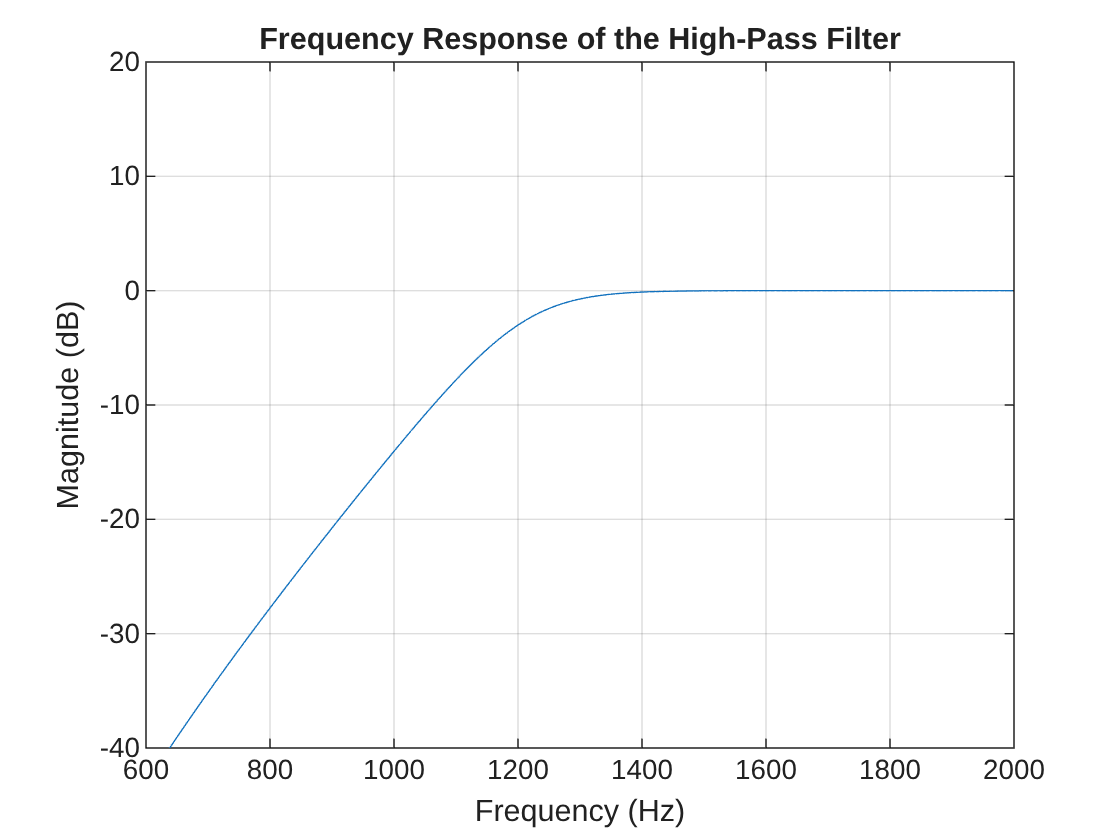

[h, f] = freqz(bd, ad, 1024, F_s);

figure();
plot(f, 20*log10(abs(h)));
ylim([-40 20]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response of the High-Pass Filter');
grid on;

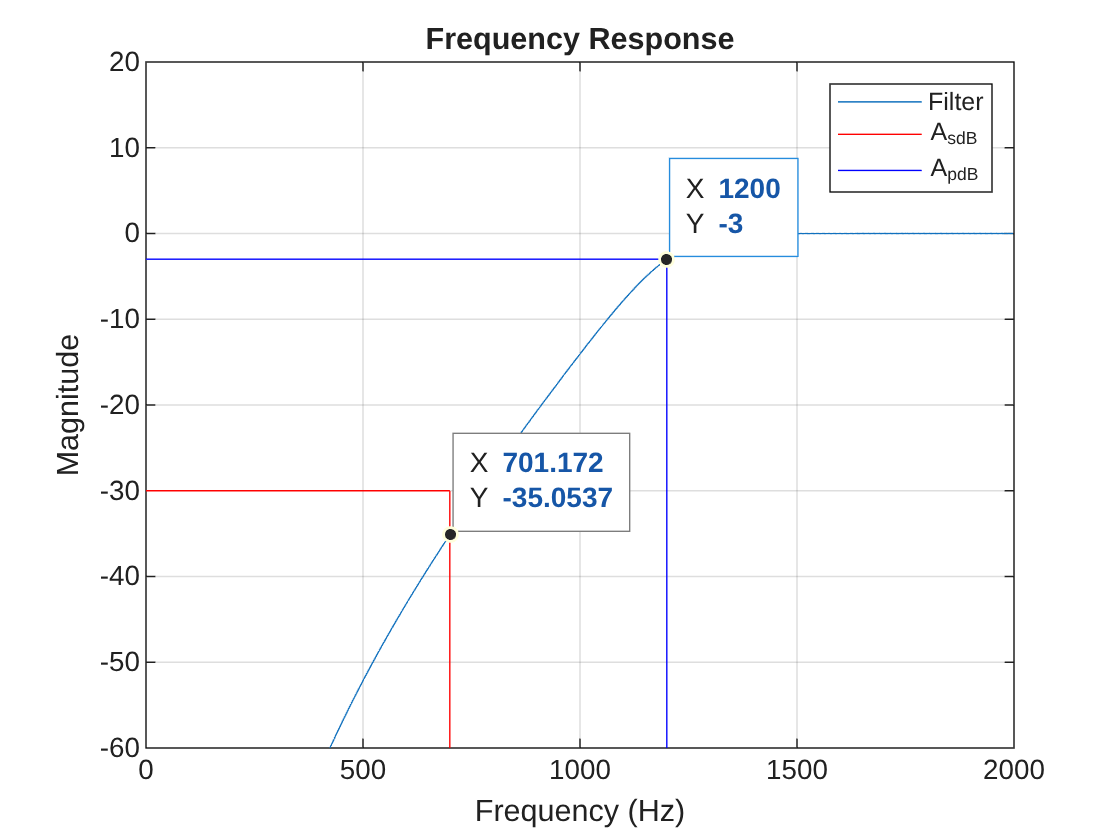

    plot(f, 20*log10(abs(h)))
    ylim([-60 20]);
    line([f_s f_s],[-A_sdB -60], 'Color','r');
    line([f_p f_p], [-A_pdB -60], 'Color', 'b');
    line([0 f_s], [-A_sdB -A_sdB], 'Color', 'r');
    line([0 f_p], [-A_pdB -A_pdB], 'Color', 'b');

    %labels
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title('Frequency Response');
    legend('Filter', 'A_{sdB}','A_{pdB}');
    grid on;

ax = gca;
chart = ax.Children(5);
datatip(chart,701.2,-35.05);
chart = ax.Children(1);
datatip(chart,1200,-3);

Her ses, at ved A_s er der en dæmpning på 35dB og ved A_p er der 3dB dæmpning, dvs. at filteret opfylder kravene.